# Programming Assignment 3

## Clear Environment

clc;
clear all;
close all;
warning ('off', 'all'); % Stopping all warnings
sympref('AbbreviateOutput', false);
sympref('MatrixWithSquareBrackets', true);
sympref('PolynomialDisplayStyle', 'ascend');
speed_solve = true;

## System Parameters

% Actual Physical Parameters
am1 = 1;am2 = 1;
al1 = 1;al2 = 1;
ar1 = 0.45;ar2 = 0.45;
aI1 = 0.084;aI2 = 0.084;
gravity = 9.81;

% Nomimal Paramters
nm1 = 0.75;nm2 = 0.75;
nI1 = 0.063;nI2 = 0.063;
nr1 = aI1;nr2 = aI2;

## Part 4.2.1: Initial Setup

## a): Trajectory Generation

% Joint 1
theta0 = deg2rad(180);
thetaf = 0;
theta0_dot = 0;
thetaf_dot = 0;
t0 = 0;
tf = 10;
trajectory_generation;
q1d = q

$$q1d = \pi -\frac{3\,\pi \,t^{2}}{100}+\frac{\pi \,t^{3}}{500}$$

dq1d = diff(q,t)

$$dq1d = -\frac{3\,\pi \,t}{50}+\frac{3\,\pi \,t^{2}}{500}$$

v1d = diff(q,t,2)

$$v1d = -\frac{3\,\pi }{50}+\frac{3\,\pi \,t}{250}$$

clear q

% Joint 2
theta0 = deg2rad(90);
thetaf = 0;
theta0_dot = 0;
thetaf_dot = 0;
t0 = 0;
tf = 10;
trajectory_generation;
q2d = q

$$q2d = \frac{\pi }{2}-\frac{3\,\pi \,t^{2}}{200}+\frac{\pi \,t^{3}}{1000}$$

dq2d = diff(q,t)

$$dq2d = -\frac{3\,\pi \,t}{100}+\frac{3\,\pi \,t^{2}}{1000}$$

v2d = diff(q,t,2)

$$v2d = -\frac{3\,\pi }{100}+\frac{3\,\pi \,t}{500}$$

clear q

## b): Manipulator Form

syms I1 I2 m1 m2 r1 r2 l1 l2 q1 q2 dq1 dq2 ddq1 ddq2 g U1 U2 v1 v2
a = I1 + I2 + m1*r1^2 + m2*(l1^2 + r2^2);
b = m2*l1*r2;
d = I2 + m2*r2^2;
Mmat= [a+2*b* cos(q2), d+b* cos(q2); d+b* cos(q2), d];
Cmat= [-b* sin(q2)*dq2, -b* sin(q2)*(dq1+dq2); b* sin(q2)*dq1,0];
Gmat= [-m1*g*r1* sin(q1)-m2*g*(l1* sin(q1)+r2* sin(q1+q2)); -m2*g*r2* sin(q1+q2)];
T = simplify(Mmat*[ddq1;ddq2] + Cmat*[dq1;dq2] + Gmat); % Robot Dynamics
T = subs(T,[I1,I2,m1,m2,r1,r2,l1,l2,g],[aI1,aI2,am1,am2,ar1,ar2,al1,al2,gravity])

$$T = \left[\begin{array}{c} {\mathrm{ddq}}_{1}\,\left(\frac{9\,\cos\left(q_{2}\right)}{10}+\frac{1573}{1000}\right)-\frac{28449\,\sin\left(q_{1}\right)}{2000}-\frac{8829\,\sin\left(q_{2}+q_{1}\right)}{2000}+{\mathrm{ddq}}_{2}\,\left(\frac{9\,\cos\left(q_{2}\right)}{20}+\frac{573}{2000}\right)-\frac{9\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right)}{20}-\frac{9\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right)\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{1}\right)}{20}\\ \frac{573\,{\mathrm{ddq}}_{2}}{2000}-\frac{8829\,\sin\left(q_{2}+q_{1}\right)}{2000}+\frac{9\,{{\mathrm{dq}}_{1}}^{2}\,\sin\left(q_{2}\right)}{20}+{\mathrm{ddq}}_{1}\,\left(\frac{9\,\cos\left(q_{2}\right)}{20}+\frac{573}{2000}\right) \end{array}\right]$$

[ddq1, ddq2] = solve(T-[U1;U2],[ddq1,ddq2]);
ddq = [ddq1;ddq2];
control_input = simplify(Mmat*[v1;v2] + Cmat*[dq1;dq2] + Gmat); % Control Input
control_input = simplify(subs(control_input,[I1,I2,m1,m2,r1,r2,l1,l2,g],[nI1,nI2,nm1,nm2,nr1,nr2,al1,al2,gravity]))

$$control\_input = \left[\begin{array}{c} v_{1}\,\left(\frac{63\,\cos\left(q_{2}\right)}{500}+\frac{110823}{125000}\right)-\frac{797553\,\sin\left(q_{1}\right)}{100000}-\frac{61803\,\sin\left(q_{2}+q_{1}\right)}{100000}+v_{2}\,\left(\frac{63\,\cos\left(q_{2}\right)}{1000}+\frac{17073}{250000}\right)-\frac{63\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right)}{1000}-\frac{63\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right)\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{1}\right)}{1000}\\ \frac{17073\,v_{2}}{250000}-\frac{61803\,\sin\left(q_{2}+q_{1}\right)}{100000}+\frac{63\,{{\mathrm{dq}}_{1}}^{2}\,\sin\left(q_{2}\right)}{1000}+v_{1}\,\left(\frac{63\,\cos\left(q_{2}\right)}{1000}+\frac{17073}{250000}\right) \end{array}\right]$$

## 4.2.2 Robust Control Design

## C): Robust Control Law Design

A = [zeros(2) eye(2);zeros(2) zeros(2)] % A = [0 I; 0 0]

A =      0     0     1     0
     0     0     0     1
     0     0     0     0
     0     0     0     0


B = [zeros(2); eye(2)] % B = [0;I]

B =      0     0
     0     0
     1     0
     0     1


lambda = [-3, -3, -4, -4]; % Eigen Values of system
K = place(A,B,lambda)

K =     12     0     7     0
     0    12     0     7


Acl = A - B*K

Acl =      0     0     1     0
     0     0     0     1
   -12     0    -7     0
     0   -12     0    -7


Q = eye(4)*10

Q =     10     0     0     0
     0    10     0     0
     0     0    10     0
     0     0     0    10


P = lyap(Acl',Q)% Acl'*P + P*Acl = -Q

P =    12.2024         0    0.4167         0
         0   12.2024         0    0.4167
    0.4167         0    0.7738         0
         0    0.4167         0    0.7738


rho = 3.5

rho = 3.5000

## E): Simulate the System W/O Boundary Layer

phi = 0

phi = 0

enable_robust_control = true

enable_robust_control = logical
   1


initial_params =     3.4907
    2.1817
         0
         0


Simulating System


t_size = 175713

Calculating System Parameters for Plotting
Plotting System


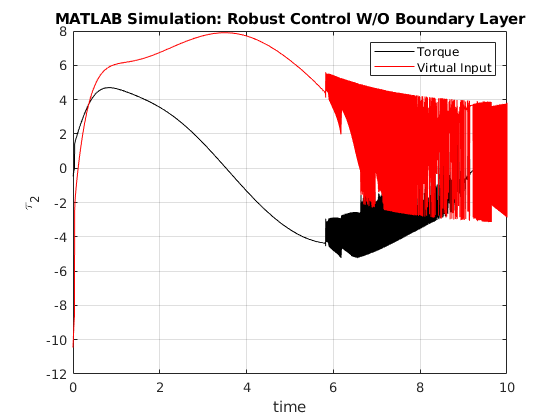

system_type = "MSWRCNBL";
graph_title = "MATLAB Simulation: Robust Control W/O Boundary Layer";
simulate_system;

x_rcwobl = state_space_matrix;
v_rcwobl = virtual_input;
tau_rcwobl = system_input;
time_rcwobl =time_points;
tau1_max = max(tau_rcwobl(:, 1))

tau1_max = 6.6485

tau1_min = min(tau_rcwobl(:, 1))

tau1_min = -20.1039

tau2_max = max(tau_rcwobl(:, 2))

tau2_max = 4.6970

tau2_min = min(tau_rcwobl(:, 2))

tau2_min = -5.2293

## F): Simulate the System W Boundary Layer

phi = 0.1

phi = 0.1000

enable_robust_control = true

enable_robust_control = logical
   1


system_type = "MSWRCWBL"

system_type = "MSWRCWBL"

graph_title = "MATLAB Simulation: Robust Control W Boundary Layer"

graph_title = "MATLAB Simulation: Robust Control W Boundary Layer"

initial_params =     3.4907
    2.1817
         0
         0


Simulating System


t_size = 337

Calculating System Parameters for Plotting
Plotting System


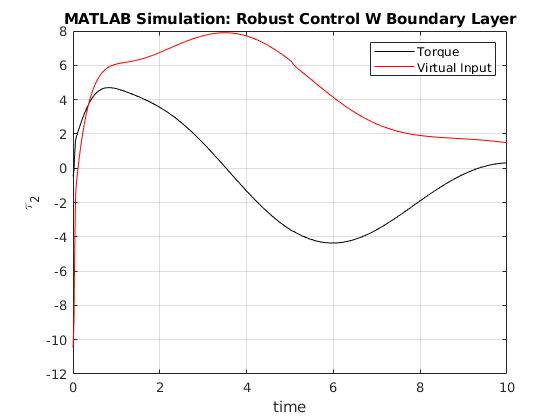

simulate_system;

x_rcwbl = state_space_matrix;
v_rcwbl = virtual_input;
tau_rcwbl = system_input;
time_rcwbl = time_points;
tau1_max = max(tau_rcwbl(:, 1))

tau1_max = 6.2892

tau1_min = min(tau_rcwbl(:, 1))

tau1_min = -18.4266

tau2_max = max(tau_rcwbl(:, 2))

tau2_max = 4.6972

tau2_min = min(tau_rcwbl(:, 2))

tau2_min = -4.3648

## G): Simulate the System W/O Robust Control

phi = 0

phi = 0

enable_robust_control = false

enable_robust_control = logical
   0


system_type = "MSWNRC"

system_type = "MSWNRC"

graph_title = "MATLAB Simulation: Non Robust Control"

graph_title = "MATLAB Simulation: Non Robust Control"

initial_params =     3.4907
    2.1817
         0
         0


Simulating System


t_size = 153

Calculating System Parameters for Plotting
Plotting System


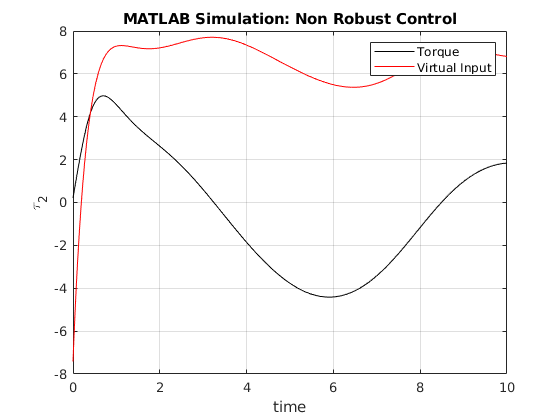

simulate_system;

x_nrc = state_space_matrix;
v_nrc = virtual_input;
tau_nrc = system_input;
time_nrc = time_points;
tau1_max = max(tau_nrc(:, 1))

tau1_max = 5.7893

tau1_min = min(tau_nrc(:, 1))

tau1_min = -18.6573

tau2_max = max(tau_nrc(:, 2))

tau2_max = 4.9818

tau2_min = min(tau_nrc(:, 2))

tau2_min = -4.4127

## H): Gazebo Simulation

system_type = "GSWRCWBL"

system_type = "GSWRCWBL"

graph_title = "Gazebo Simulation: Robust Control with Boundary Layer"

graph_title = "Gazebo Simulation: Robust Control with Boundary Layer"

The value of the ROS_MASTER_URI environment variable, http://localhost:11311, will be used to connect to the ROS master.
Initializing global node /matlab_global_node_18857 with NodeURI http://Ubuntu-20:37819/


A =      0     0     1     0
     0     0     0     1
   -12     0    -7     0
     0   -12     0    -7


Shutting down global node /matlab_global_node_18857 with NodeURI http://Ubuntu-20:37819/


enable_robust_control = true;
rrbot_traj_control;

t_size = 260

Calculating System Parameters for Plotting
Plotting System


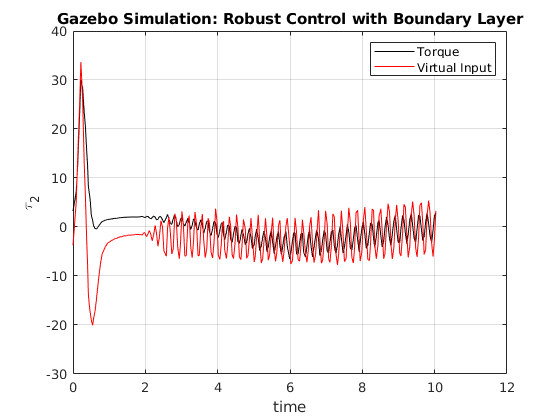

plot_system;

x_gsrcwobl = state_space_matrix;
v_gsrcwobl = virtual_input;
tau_gsrcwobl = system_input;
time_gsrcwobl =time_points;
tau1_max = max(tau_gsrcwobl(:, 1))

tau1_max = 68.0895

tau1_min = min(tau_gsrcwobl(:, 1))

tau1_min = -23.9650

tau2_max = max(tau_gsrcwobl(:, 2))

tau2_max = 29.9985

tau2_min = min(tau_gsrcwobl(:, 2))

tau2_min = -6.5811

## G): Comparing Different System Controls

system_type = "comparision"

system_type = "comparision"

graph_title = "Control Strategies Comparision"

graph_title = "Control Strategies Comparision"

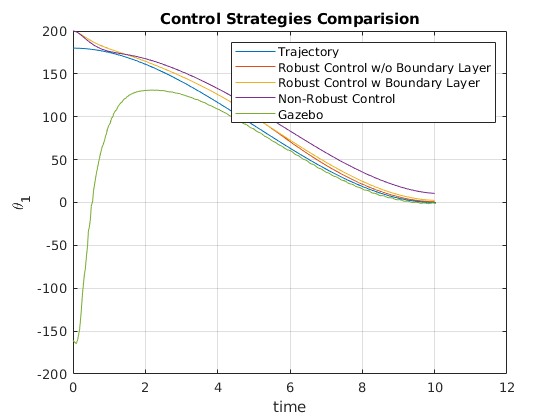

command = append('mkdir -p ','Photos/',system_type);
system(command);
% Plot Trajectories
plot(time_gsrcwobl, rad2deg(theta_plot_points(:, 1)))
hold on;
plot(time_rcwobl, rad2deg(x_rcwobl(:, 1)))
hold on;
plot(time_rcwbl, rad2deg(x_rcwbl(:, 1)))
hold on;
plot(time_nrc, rad2deg(x_nrc(:, 1)))
hold on;
plot(time_gsrcwobl, rad2deg(x_gsrcwobl(:, 1)))
hold on;
legend('Trajectory', 'Robust Control w/o Boundary Layer', 'Robust Control w Boundary Layer', 'Non-Robust Control','Gazebo')
hold off;
grid on;
xlabel('time');
ylabel('\theta_{1}')
title(graph_title)
saveas(gcf, append('Photos/',system_type,'/',system_type,"theta1.jpg"))

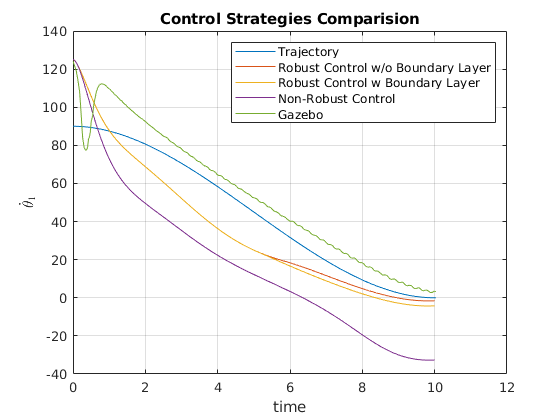


plot(time_gsrcwobl, rad2deg(theta_plot_points(:, 2)))
hold on;
plot(time_rcwobl, rad2deg(x_rcwobl(:, 2)))
hold on;
plot(time_rcwbl, rad2deg(x_rcwbl(:, 2)))
hold on;
plot(time_nrc, rad2deg(x_nrc(:, 2)))
hold on;
plot(time_gsrcwobl, rad2deg(x_gsrcwobl(:, 2)))
hold on;
legend('Trajectory', 'Robust Control w/o Boundary Layer', 'Robust Control w Boundary Layer', 'Non-Robust Control','Gazebo')
hold off;
grid on;
xlabel('time');
ylabel('$\dot{\theta}_{1}$', 'Interpreter', 'latex')
title(graph_title)
saveas(gcf, append('Photos/',system_type,'/',system_type,"dtheta1.jpg"))

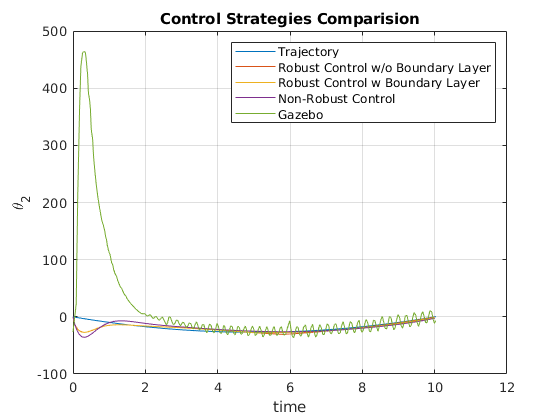


plot(time_gsrcwobl, rad2deg(theta_plot_points(:, 3)))
hold on;
plot(time_rcwobl, rad2deg(x_rcwobl(:, 3)))
hold on;
plot(time_rcwbl, rad2deg(x_rcwbl(:, 3)))
hold on;
plot(time_nrc, rad2deg(x_nrc(:, 3)))
hold on;
plot(time_gsrcwobl, rad2deg(x_gsrcwobl(:, 3)))
hold on;
legend('Trajectory', 'Robust Control w/o Boundary Layer', 'Robust Control w Boundary Layer', 'Non-Robust Control','Gazebo')
hold off;
grid on;
xlabel('time');
ylabel('\theta_{2}')
title(graph_title)
saveas(gcf, append('Photos/',system_type,'/',system_type,"theta2.jpg"))

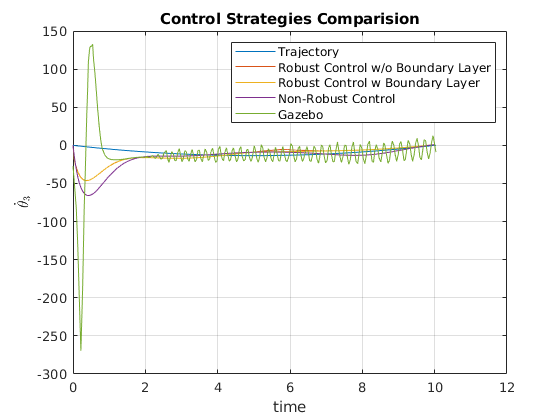


plot(time_gsrcwobl, rad2deg(theta_plot_points(:, 4)))
hold on;
plot(time_rcwobl, rad2deg(x_rcwobl(:, 4)))
hold on;
plot(time_rcwbl, rad2deg(x_rcwbl(:, 4)))
hold on;
plot(time_nrc, rad2deg(x_nrc(:, 4)))
hold on;
plot(time_gsrcwobl, rad2deg(x_gsrcwobl(:, 4)))
hold on;
legend('Trajectory', 'Robust Control w/o Boundary Layer', 'Robust Control w Boundary Layer', 'Non-Robust Control','Gazebo')
hold off;
grid on;
xlabel('time');
ylabel('$\dot{\theta}_{3}$', 'Interpreter', 'latex')
title(graph_title)
saveas(gcf, append('Photos/',system_type,'/',system_type,"dtheta3.jpg"))

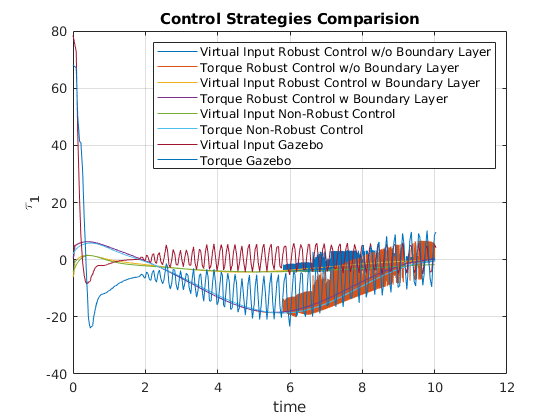



plot(time_rcwobl, v_rcwobl(:, 1))
hold on;
plot(time_rcwobl, tau_rcwobl(:, 1))
hold on;
plot(time_rcwbl, v_rcwbl(:, 1))
hold on;
plot(time_rcwbl, tau_rcwbl(:, 1))
hold on;
plot(time_nrc, v_nrc(:, 1))
hold on;
plot(time_nrc, tau_nrc(:, 1))
hold on;
plot(time_gsrcwobl, v_gsrcwobl(:, 1))
hold on;
plot(time_gsrcwobl, tau_gsrcwobl(:, 1))
hold on;
legend('Virtual Input Robust Control w/o Boundary Layer','Torque Robust Control w/o Boundary Layer', 'Virtual Input Robust Control w Boundary Layer', 'Torque Robust Control w Boundary Layer', 'Virtual Input Non-Robust Control', 'Torque Non-Robust Control','Virtual Input Gazebo','Torque Gazebo')
hold off;
grid on;
xlabel('time');
ylabel('\tau_{1}')
title(graph_title)
saveas(gcf, append('Photos/',system_type,'/',system_type,"control1.jpg"))

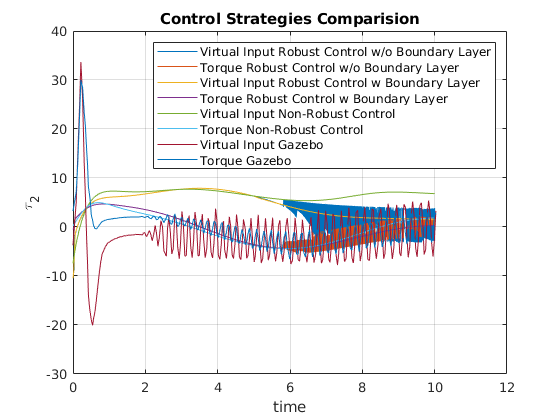



plot(time_rcwobl, v_rcwobl(:, 2))
hold on;
plot(time_rcwobl, tau_rcwobl(:, 2))
hold on;
plot(time_rcwbl, v_rcwbl(:, 2))
hold on;
plot(time_rcwbl, tau_rcwbl(:, 2))
hold on;
plot(time_nrc, v_nrc(:, 2))
hold on;
plot(time_nrc, tau_nrc(:, 2))
hold on;
plot(time_gsrcwobl, v_gsrcwobl(:, 2))
hold on;
plot(time_gsrcwobl, tau_gsrcwobl(:, 2))
hold on;
legend('Virtual Input Robust Control w/o Boundary Layer','Torque Robust Control w/o Boundary Layer', 'Virtual Input Robust Control w Boundary Layer', 'Torque Robust Control w Boundary Layer', 'Virtual Input Non-Robust Control', 'Torque Non-Robust Control','Virtual Input Gazebo','Torque Gazebo')
hold off;
grid on;
xlabel('time');
ylabel('\tau_{2}')
title(graph_title)
saveas(gcf, append('Photos/',system_type,'/',system_type,"control2.jpg"))